# Worksheet 2

## Dahlquist’s test equation:


$$\dot x = \lambda x$$


with initial condition


$$x(0) = 1$$


The analytical solution is given by


$$x(t) = e^{\lambda t}$$


For this worksheet we set $\lambda  = -1$.

We use this rather simple equation with a known exact solution to examine the properties of different numerical methods.

a) Use MATLAB to plot the function $x(t)$ for $t \in [0, 5]$ in a graph.

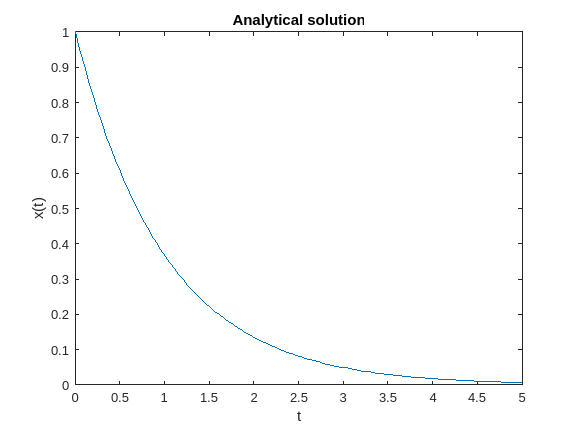

lambda = -1;
t = linspace(0,5);
x = @(t) exp(lambda*t);
plot(t,x(t))
xlabel('t')
ylabel('x(t)')
title('Analytical solution')

b) Consider a general initial value problem

$\dot y = f(y)$, $y(0) = y_0$.

Implement the following explicit numerical methods as a MATLAB function depending on the initial value $y_0$, the time step size $\delta t$, the end time $t_{\text{end}}$, and the right hand side $f(y)$, i.e.:

`function y = expl_euler(y_0, dt, t_end, f)`.

The output of the function shall be a vector containing all approximate values for $y$, including $y_0$.

1) explicit Euler method (implemented in a separate file)

    `function y = expl_euler(y_0, dt, t_end, f)`

`    t = 0:dt:t_end;`

`    y = zeros(1, length(t));`

`    y(1) = y_0;`

`    for n = 1:length(t)-1`

`        y(n+1) = y(n) + dt * f(y(n));`

`    end`

`    end`

2) method of Heun (implemented in a separate file)

    `function y = expl_heun(y_0, dt, t_end, f)`

`    t = [0:dt:t_end]';`

`    y = zeros(length(y_0),length(t));`

`    y(:,1) = y_0;`

`    for n = 1:length(t)-1`

`        k1 = f(y(:,n));`

`        k2 = f(y(:,n) + dt*k1);`

`        y(:,n+1) = y(:,n) + dt/2 * (k1+k2);`

`    end`

`    end`

3) Runge-Kutta method fourth order (implemented in a separate file)

    `function y = expl_runge_kutta(y_0, dt, t_end, f)`

    `t = 0:dt:t_end;`

    `y = zeros(1, length(t));`

    `y(1) = y_0;`

    `for n = 1:length(t)-1`

    `    k1 = f(t(n), y(n));`

    `    k2 = f(y(n)+dt/2*k1);`

    `    k3 = f(y(n)+dt/2*k2);`

    `    k4 = f(y(n)+dt*k3);`

    `    y(n+1) = y(n) + dt/6 * (k1 + 2*k2 + 2*k3 + k4);`

    `end`

    `end`

c) For each of the three methods implemented, compute approximate solutions $x_k$ for equation (1) with initial conditions (2), end time $t_{\text{end}} = 5$. We want to investigate the behavior of the approximate solutions for different time step sizes $\delta t = 1, 1/2 , 1/4 , 1/8$.

i) For each of the three methods, create a separate figure. Each figure contains the four computed solutions for the four different time steps $\delta t$, all four in one plot. Add also the analytical solution for reference in each figure.

ii) For each case, compute the approximation error defined as

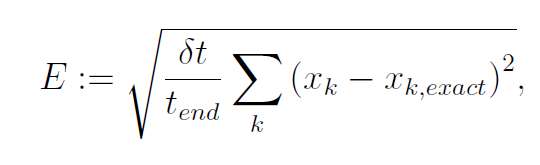

where $x_k$ denotes the approximation, $x_{k,\text{exact}}$ the exact solution at $t = \delta t k$.

    `function e = error(dt, t_end, x, x_exact)`

`    e = sqrt(dt/t_end*sum((x-x_exact).^2));`

`  end`

iii) For each of the three methods, determine the factor by which the error $E$ is reduced if the step size $\delta t$ is halved. Write down all the results (errors and error reductions) in the tables below. Also write all information needed in the tables to the MATLAB console in a readable way.

Hint: the factors should be greater than one if the errors are reduced.

1) explicit Euler method,

    i- Figure of four solutions for four time steps $\delta t$ and the analytical solution

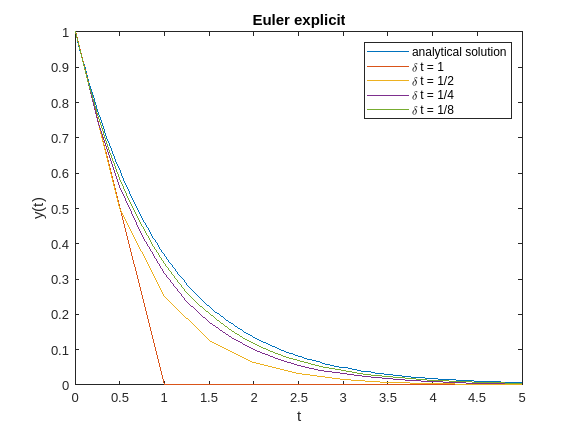

t_end = 5;
f = @(y) lambda*y;
y_0 = 1;
figure
plot(t,x(t));
hold on
i = 1;
for dt = 2.^-(0:3)
    y = expl_euler(y_0, dt, t_end, f);
    plot(0:dt:t_end,y);
    e(i) = approx_error(dt, t_end, y, x(0:dt:t_end));
    i = i+1;
end
hold off
title ('Euler explicit')
legend('analytical solution', '\delta t = 1', '\delta t = 1/2', '\delta t = 1/4', '\delta t = 1/8')
xlabel('t')
ylabel('y(t)')

    ii- The approximation error

e

e =     0.1769    0.0669    0.0303    0.0145


    iii- Error reduction factor

e_red = e(1:end-1)./e(2:end);
euler_table = table([1 e(1) nan]', [1/2 e(2) e_red(1)]', [1/4 e(3) e_red(2)]', [1/8 e(4) e_red(3)]','rownames', {'δt', 'error', 'error red.'}, 'VariableNames', {'1', '1/2', '1/4', '1/8'});
T = table(euler_table,'VariableNames',{'explicit Euler method (q=1)'}); % Nested table
disp(T)

                  explicit Euler method (q=1)              
                     1        1/2        1/4         1/8   
    _______________________________________________________

    δt                  1       0.5        0.25       0.125
    error         0.17692    0.0669    0.030274    0.014506
    error red.        NaN    2.6446      2.2098       2.087



2) method of Heun,

    i- Figure of four solutions for four time steps $\delta t$ and the analytical solution

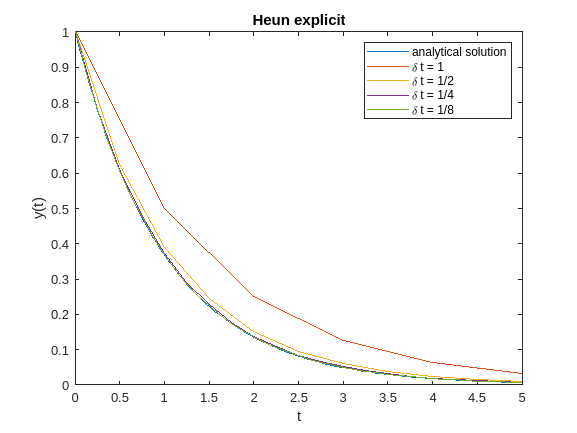

figure
plot(t,x(t));
hold on
i = 1;
for dt = 2.^-(0:3)
    y = expl_heun(y_0, dt, t_end, f);
    plot(0:dt:t_end,y);
    e(i) = approx_error(dt, t_end, y, x(0:dt:t_end));
    i = i+1;
end
hold off
title ('Heun explicit')
legend('analytical solution', '\delta t = 1', '\delta t = 1/2', '\delta t = 1/4', '\delta t = 1/8')
xlabel('t')
ylabel('y(t)')

    ii- The approximation error

e

e =     0.0881    0.0140    0.0028    0.0006


    iii- Error reduction factor

e_red = e(1:end-1)./e(2:end);
heun_table = table([1 e(1) nan]', [1/2 e(2) e_red(1)]', [1/4 e(3) e_red(2)]', [1/8 e(4) e_red(3)]','rownames', {'δt', 'error', 'error red.'}, 'VariableNames', {'1', '1/2', '1/4', '1/8'});
T = table(heun_table,'VariableNames',{'method of Heun (q=2)'}); % Nested table
disp(T)

                        method of Heun (q=2)                     
                     1          1/2          1/4          1/8    
    _____________________________________________________________

    δt                   1         0.5         0.25         0.125
    error         0.088107    0.014008    0.0028314    0.00064017
    error red.         NaN      6.2897       4.9473        4.4229



3) Runge-Kutta method (fourth order)

    i- Figure of four solutions for four time steps $\delta t$ and the analytical solution

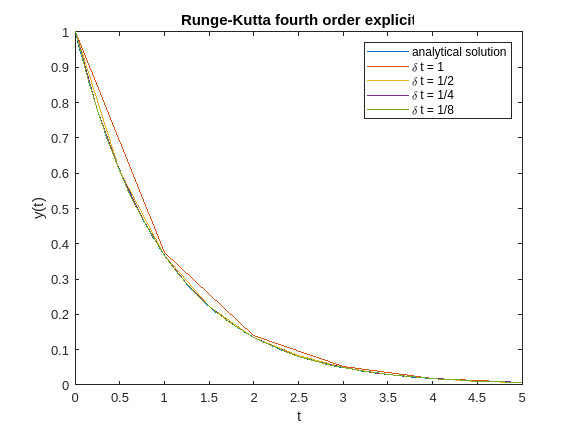

figure
plot(t,x(t));
hold on
i = 1;
for dt = 2.^-(0:3)
    y = expl_runge_kutta(y_0, dt, t_end, f);
    plot(0:dt:t_end,y);
    e(i) = approx_error(dt, t_end, y, x(0:dt:t_end));
    i = i+1;
end
hold off
title ('Runge-Kutta fourth order explicit')
legend('analytical solution', '\delta t = 1', '\delta t = 1/2', '\delta t = 1/4', '\delta t = 1/8')
xlabel('t')
ylabel('y(t)')

    ii- The approximation error

e

e =     0.0042    0.0002    0.0000    0.0000


    iii- Error reduction factor

e_red = e(1:end-1)./e(2:end);
runge_kutta_table = table([1 e(1) nan]', [1/2 e(2) e_red(1)]', [1/4 e(3) e_red(2)]', [1/8 e(4) e_red(3)]','rownames', {'δt', 'error', 'error red.'}, 'VariableNames', {'1', '1/2', '1/4', '1/8'});
T = table(runge_kutta_table,'VariableNames',{'Runge-Kutta method (q=4)'}); % Nested table
disp(T)

                        Runge-Kutta method (q=4)                     
                      1           1/2           1/4           1/8    
    _________________________________________________________________

    δt                    1           0.5          0.25         0.125
    error         0.0042417    0.00017666    8.9593e-06    5.0432e-07
    error red.          NaN        24.011        19.718        17.765



## Van-der-Pol-Oscillator:

      (3)

This nonlinear second-order ODE can be transformed to a first-order form by introducing a second variable $y = \dot x$ , resulting in the system:

            (4)

with initial conditions  $x(0) = 1 , y(0) = 1$.               (5)

For this worksheet we set $\mu = 1$.

d) Extend the Heun solver from part b) to also account for vector valued functions.

Hint: keep the function signature from the original version

e) Compute approximate solutions for equation (4) with initial conditions (5), end time $t_{\text{end}} = 20$ and time step size $\delta t = 0.1$, using the now extended method of Heun from d). In the same figure, graph in separate subplots: x vs. t, y vs. t, and also the trajectory in phase space (y vs. x).

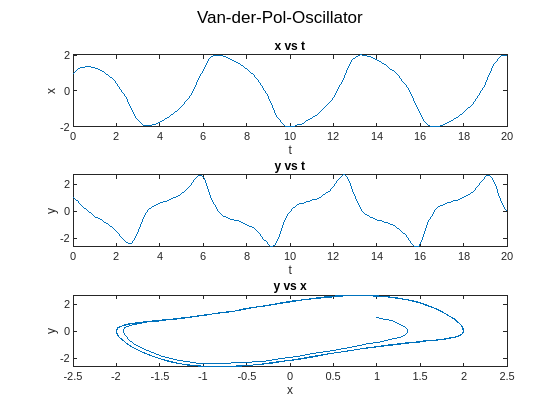

t_end = 20;
dt = .1;
mu = 1;
f = @(y) [y(2); mu*(1-y(1).^2).*y(2)-y(1)];
y_0 = [1; 1];
y = expl_heun(y_0, dt, t_end, f);
t = 0:dt:t_end;
figure
subplot(3,1,1)
plot (t,y(1,:))
xlabel('t')
ylabel('x')
title('x vs t')
subplot(3,1,2)
plot (t,y(2,:))
xlabel('t')
ylabel('y')
title('y vs t')
subplot(3,1,3)
plot (y(1,:),y(2,:))
xlabel('x')
ylabel('y')
title('y vs x')
sgtitle('Van-der-Pol-Oscillator')

Optional: In a separate figure, create a quiver plot to visualize the phase space as a vector field. (Hint: use a meshgrid)

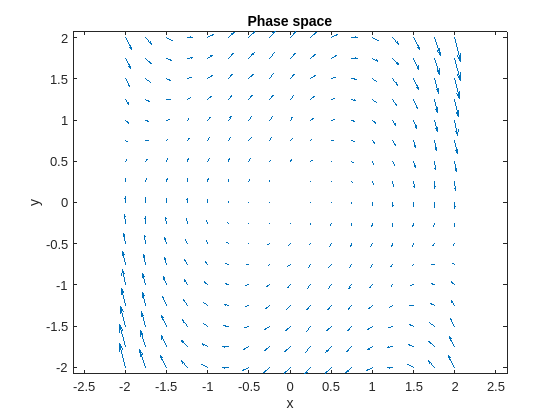

[X, Y] = meshgrid(-2:.25:2, -2:.25:2);
U = Y;
V = mu*(1-X.^2).*Y-X;
figure
quiver(X,Y,U,V)
axis equal
xlabel('x')
ylabel('y')
title('Phase space')